# Walkthrough with Intestine dataset

## Load the Data

addpath('./data')
load('Intestine_dataset.mat')

## Process data and select features

Remove low-quality cells and select features:

- filter cells don't express min_exp percentage of genes

- select top #gene_selected informative genes

min_exp = 0.95; gene_selected = 3000;
[prodata,progene_name,procell_label] = preprocessing(data,gene_name,true_label,min_exp, ...
gene_selected);

## **Consensus clustering**

If choosing SC3 package to do the consensus clustering on the processed data, we can get the following cell-cell similarity matrix M. The example scripts of using SC3 package can be found in file SC3.R.

## **Number of clusters**

The number of clusters is estimated by analyzing the largest gap of sorted eigenvalues of symmetric normalized graph Laplacian:

Number of cluster based on zero eigenvalues & Largest gap 
     1     5



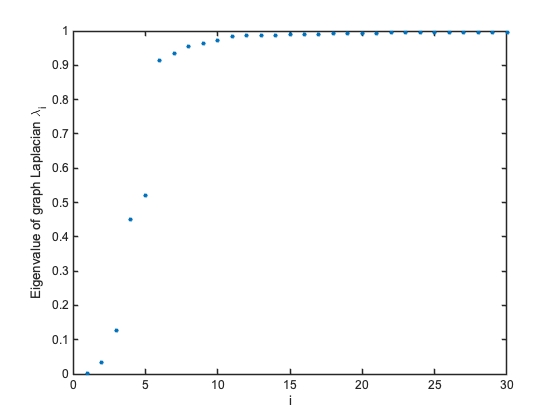

[eigenvalues] = plot_eigen_gap(M);

No_cluster = 3; 

## **Run QuanTC**

- **Soft clustering**: get the likelihoods of cells belonging to each cluster based on symmetric non-negative matrix factorization of M

- **CPI**: compute CPI value of each cell, use TC_cut to select cell with higher CPI values to be TC 

TC_cut = 0.34;
[result] = run_QuanTC(prodata,M,No_cluster,TC_cut);

- **2d-visualization**: cells are visualized through the probabilistic regularized embedding (PRE) approach

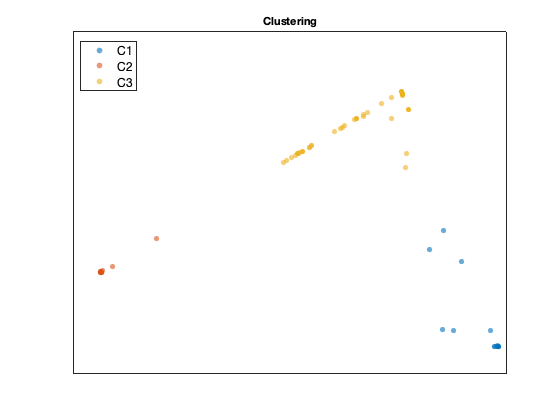

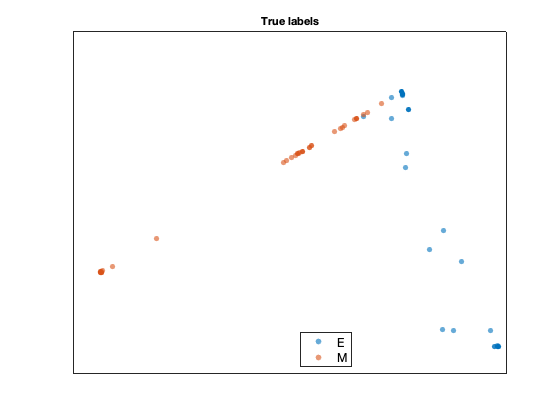

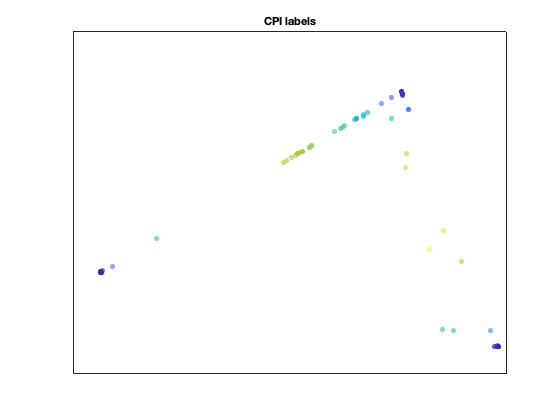

label_legend =  {'E','M'};
cell_visu_PRE(result,procell_label, label_legend)

## **Feature plot**

visualizes feature expressions on PRE

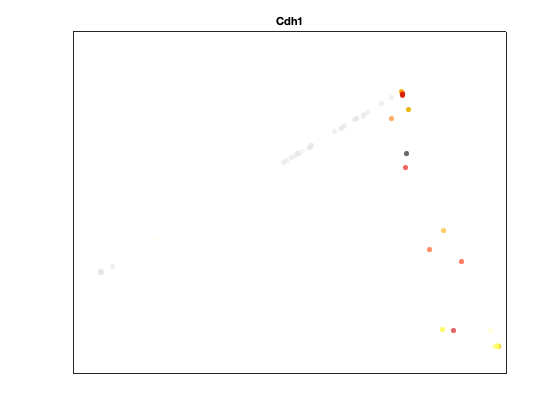

gene_plot = {'Cdh1'};
featureplot(result,prodata,progene_name,gene_plot)

## **Transition trajectory**

- **Start/ end cluster**: choose non-ICS based on the percentage of TC associated with each cluster relative to the total number of TC

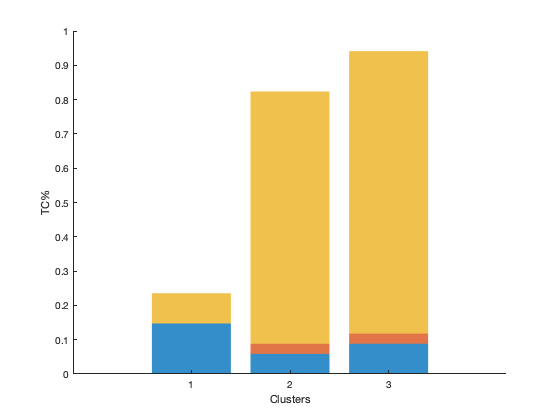

pTC(result,No_cluster)

- **Potential transition trajectories**: list the percetage of cells over whole cell population to choose the potential transition trajectories

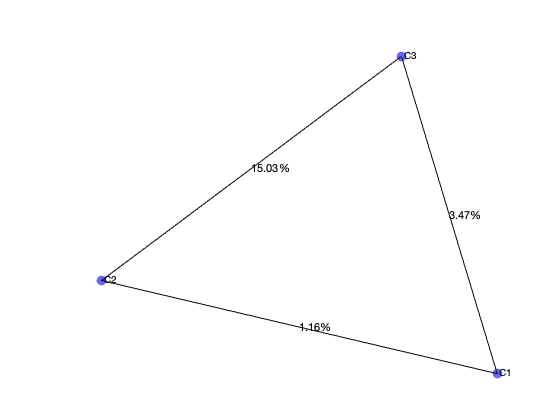

trajectory: 1  2, percentage of cells involved: 0.55491
trajectory: 1  3  2, percentage of cells involved: 0.87283


start_cluster = 1; %choose starting cluster based on the above graph
%plot TC% between clusters among all the cells
[path,ordered_cell] = traj(result,start_cluster,No_cluster); 

## **Finding cluster marker genes and the transition genes that mark transition from one trajectory**

lam2 = 10; path_id =2;
[marker_gene,transition_gene] = markers(result,prodata,M,path{path_id},ordered_cell{path_id},lam2)

ans = 1.0000

Consistency of clustering: 1


marker_gene = 3×1 cell array
    {516×1 double}
    {821×1 double}
    {926×1 double}


transition_gene = 2×2 cell array
    {10×1 double}    {16×1 double}
    {21×1 double}    {44×1 double}


## **Heatmap**

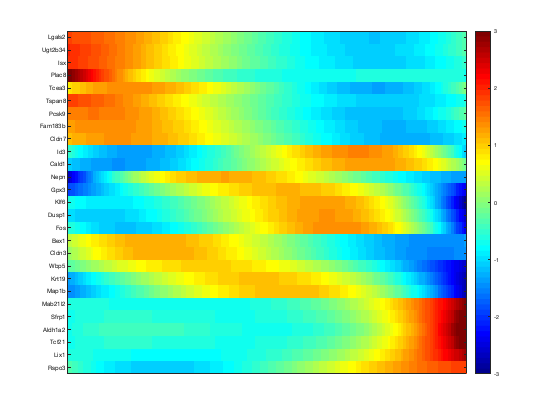

a = 5; b = 3; %plot top a marker genes and top 2b transition genes
[gene_plot,gene_cluster] = heatmap(prodata,marker_gene,transition_gene,path{path_id}, ...
ordered_cell{path_id},progene_name,a,b);

## **Plot transition genes along the transiton trajectory**

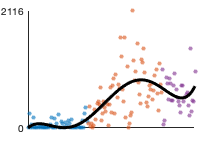

trans_gene_plot = transition_gene{1,1}(1);
tran_gene_plot(result,prodata,trans_gene_plot,path{path_id},ordered_cell{path_id},progene_name)